Problem 1:

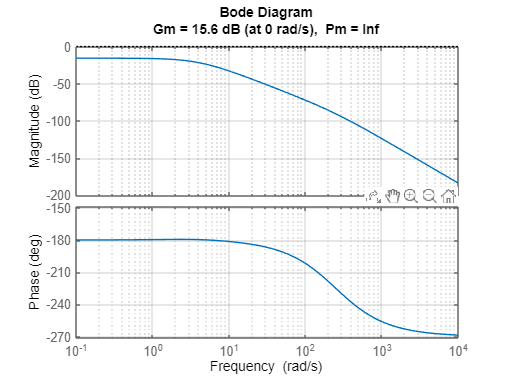

s = tf('s');
G = 666.3/(((s^3)+(250.2*(s^2))+(29.74*s)-4033));
margin(G)
grid on

fb = bandwidth(G);

Problem 2:

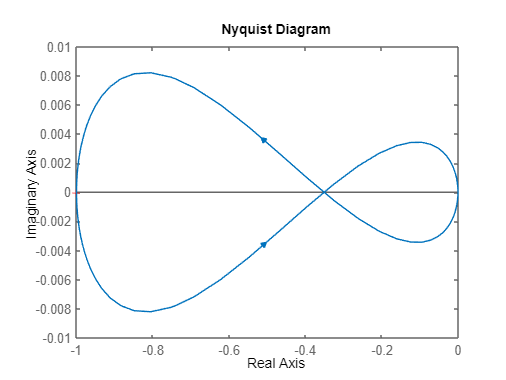

k = 6.052;
h = nyquistplot(k*G);

Problem 3:

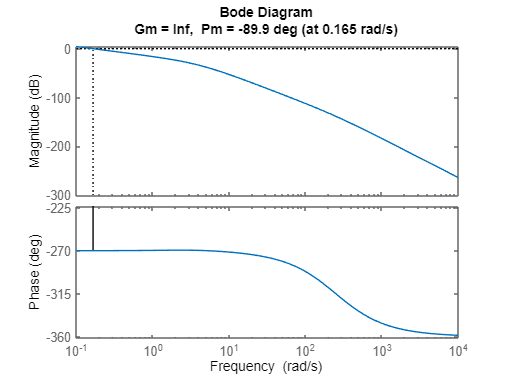

G1 = G/s;
margin(G1);

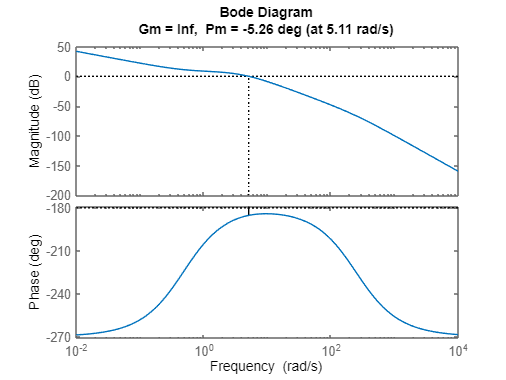

k1 = 10^(17.6/20);
Gpd1 = k1*(1/0.48*s+1);
G2 = series(Gpd1,G1);
margin(G2);

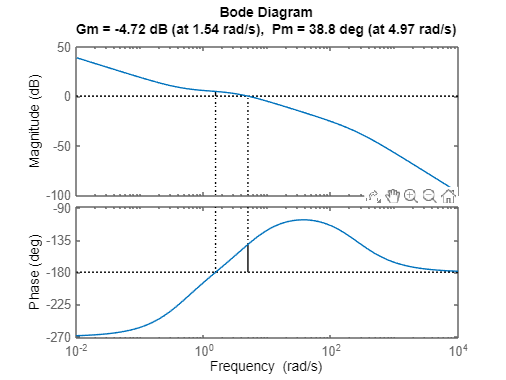

k2 = 10^(-3.2/20);
Gpd2 = k2*((1/5.11)*s+1);
G3 = series(Gpd2, G2);
margin(G3)

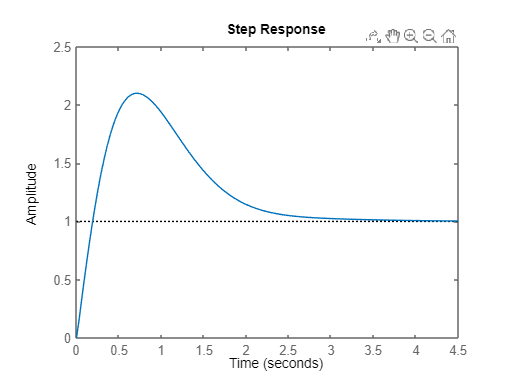

step(feedback(G3,1))

Problem 4:

fbc = bandwidth(G3);

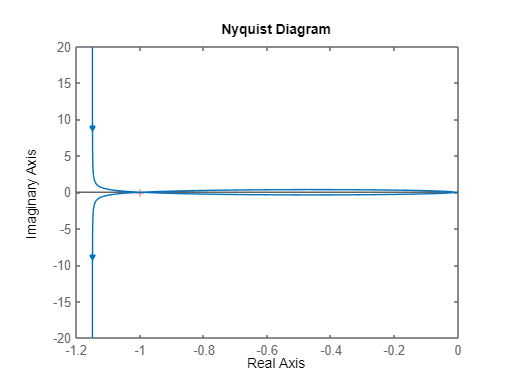

k3 = 0.58;
nyquistplot(k3*G3)